ads2=audioDatastore("voice","IncludeSubfolders",true,"LabelSource","foldernames","FileExtensions",".wav");
data=table(ads2.Files,ads2.Labels);
[traind, testd]=splitEachLabel(ads2,0.8);
traind_count=countEachLabel(traind);
testd_count=countEachLabel(testd);
reset(traind)
sr2=inf.SampleRate;
labels=[];
feat=[];
sr=[];

while hasdata(traind)
    [audioIn,inf] = read(traind);
    sr1=inf.SampleRate;
    aFE = audioFeatureExtractor("SampleRate",sr1, "Window",hamming(round(0.03*sr1),"periodic"), "OverlapLength",round(0.02*sr1), "mfcc",true, "mfccDelta",true, "pitch",true, "spectralCentroid",true);
    features = extract(aFE,audioIn(:,1));
    label=repelem(inf.Label,size(features,1));
    sr=[sr;sr1];
    feat = [feat;features];
    labels = [labels,label];
    lab=labels';
    yo=table(feat,lab);
    idx = info(aFE);
end

Mean = mean(feat,1,"omitnan");
Std = std(feat,[],1,"omitnan");
feat = (feat-Mean)./Std;

classifier=fitcknn(feat,labels,'Distance','euclidean','NumNeighbors',5,'DistanceWeight','squaredinverse','Standardize',false,'ClassNames',unique(labels));
k = 5;
group = labels;
c = cvpartition(group,'KFold',k); % 5-fold stratified cross validation
partitionedModel = crossval(classifier,'CVPartition',c);
validationAccuracy = 1 - kfoldLoss(partitionedModel,'LossFun','ClassifError');
fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);


Validation accuracy = 63.08%


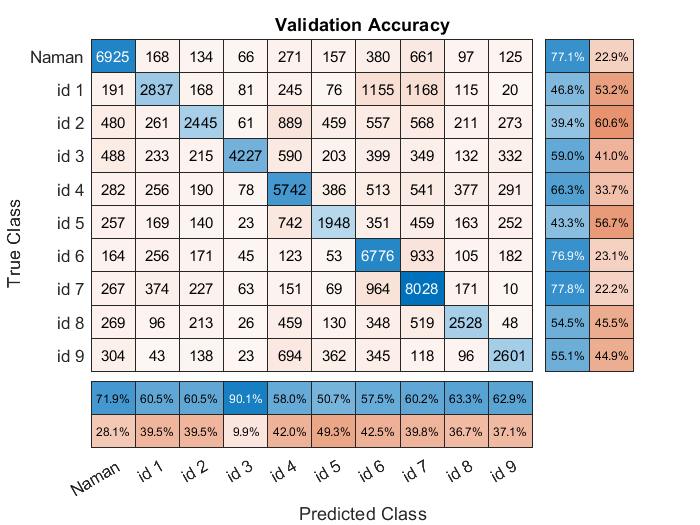


validPredictions = kfoldPredict(partitionedModel);
figure
cm = confusionchart(labels,validPredictions,'title','Validation Accuracy');
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

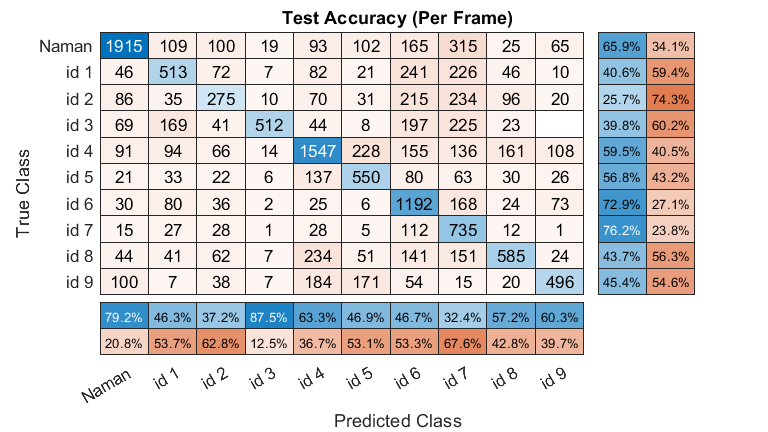

labels=[];
feat=[];
nvpf=[];
while hasdata(testd)
    [audioIn,inf] = read(testd);
    sr1=inf.SampleRate;
    aFE = audioFeatureExtractor("SampleRate",sr1, "Window",hamming(round(0.03*sr1),"periodic"), "OverlapLength",round(0.02*sr1), "mfcc",true, "mfccDelta",true, "pitch",true, "spectralCentroid",true);
    features = extract(aFE,audioIn(:,1));
    numVec = size(features,1);
    label=repelem(inf.Label,numVec);
    nvpf = [nvpf,numVec];
    feat = [feat;features];
    labels = [labels,label];
    idx = info(aFE);
end
Mean2 = mean(feat,1,"omitnan");
Std2 = std(feat,[],1,"omitnan");
feat = (feat-Mean2)./Std2;

prediction = predict(classifier,feat);
prediction = categorical(string(prediction));

figure('Units','normalized','Position',[0.4 0.4 0.4 0.4])
cm = confusionchart(labels,prediction,'title','Test Accuracy (Per Frame)');
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

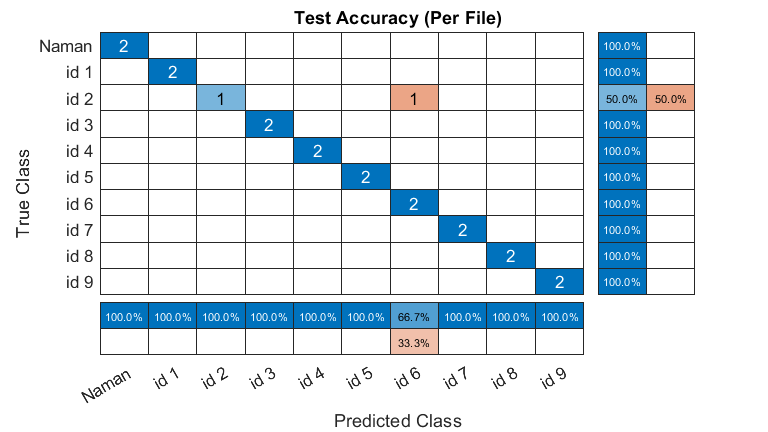


real=prediction(1:numel(testd.Files));
id=1;
for i = 1:numel(testd.Files)
    real(i) = mode(prediction(id:id+nvpf(i)-1));
    id = id + nvpf(i);
end

figure('Units','normalized','Position',[0.4 0.4 0.4 0.4])
cm = confusionchart(testd.Labels,real,'title','Test Accuracy (Per File)');
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

missclass1=(sum(real~=testd.Labels)/numel(testd.Labels))*100;